% Read the WAV file
[y, Fs] = audioread('original_audio.wav');

Error using audioread>readaudio
The filename specified was not found in the MATLAB path.

Error in audioread (line 160)
    [y, Fs] = readaudio (filename, range, datatype);


% creates a time vector t corresponding to each sample in y
% convert sample indices to seconds by dividing by F
t = (0:length(y)-1) / Fs;


## Original Audio Signal

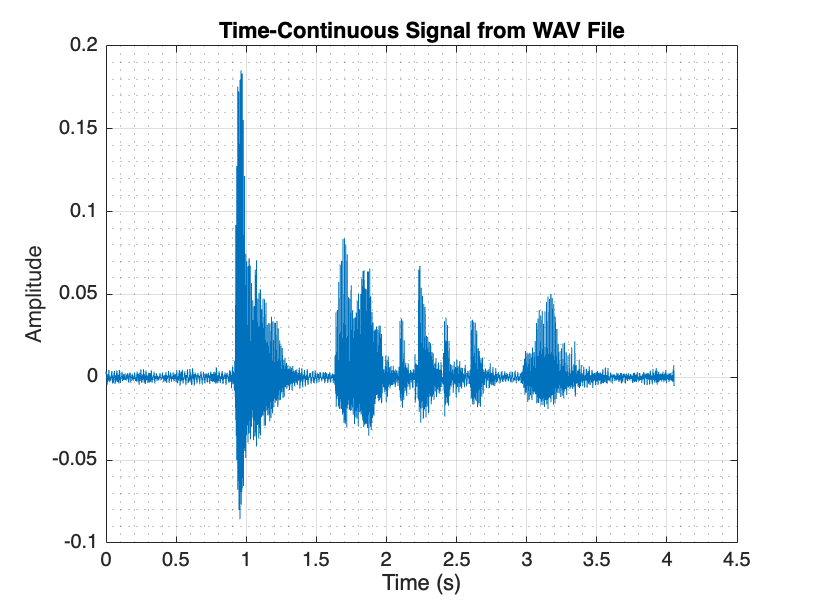

% Plot the time-continuous signal
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Continuous Signal from WAV File');
grid on;
grid minor;

## Output values

disp("Audio data (amplitude values), y =  ")

Audio data (amplitude values), y =  


disp(y(1:5)); disp("to ")

    0.0017
    0.0018
    0.0018
    0.0019
    0.0019

to 


disp(y(end))

   -0.0042



disp("The sampling frequency (samples per second), Fs = ")

The sampling frequency (samples per second), Fs = 


disp(Fs)

       48000



## Signal sampling

% Define a downsampling factor
downsample_factor = 10;

% Downsample the signal
% Downsample y, start at 1, increment by downsample_factor till the end of
% y
% Do same with t, giving corresponding time
y_downsampled = y(1:downsample_factor:end)
t_downsampled = t(1:downsample_factor:end)


## Sampled Signal

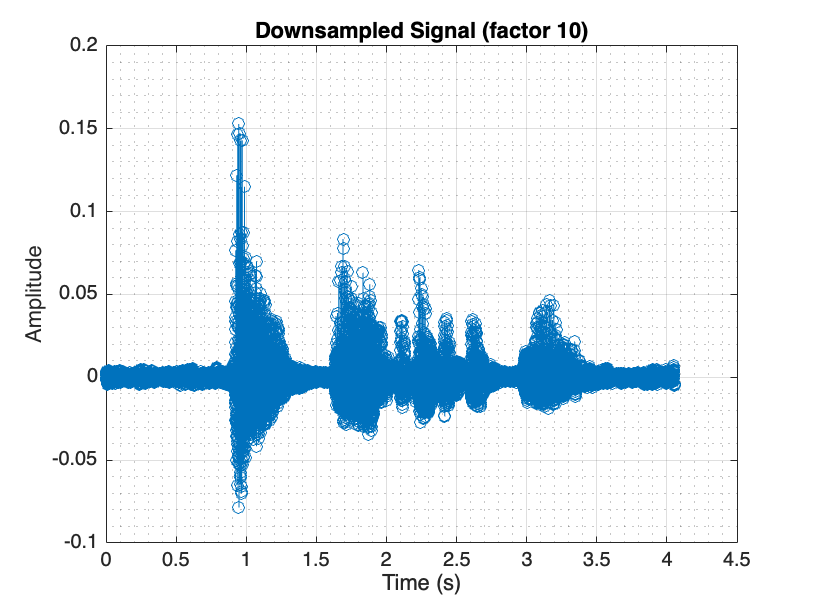

plot(t_downsampled, y_downsampled, 'o-');
title(['Downsampled Signal (factor ' num2str(downsample_factor) ')']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
grid minor;

## Quantization

% Quantization process
% Calculate the number of quantization levels (2^bits)
bits = 16;  
levels = 2^bits;

% Find the range of the signal
max_val = max(y_downsampled);
min_val = min(y_downsampled);
range = max_val - min_val;

% Calculate the step size
step_size = range / levels;

% Quantize the downsampled signal
% First normalize to 0-1 range
y_normalized = (y_downsampled - min_val) / range;
% Quantize to specified number of levels
y_quantized = round(y_normalized * (levels-1)) / (levels-1);
% Scale back to original range
y_quantized = y_quantized * range + min_val;

t_reconstructed = t;
y_reconstructed_spline = interp1(t_downsampled, y_quantized, t_reconstructed, 'spline');
y_reconstructed_linear = interp1(t_downsampled, y_quantized, t_reconstructed, 'linear');


## Quantized Signal

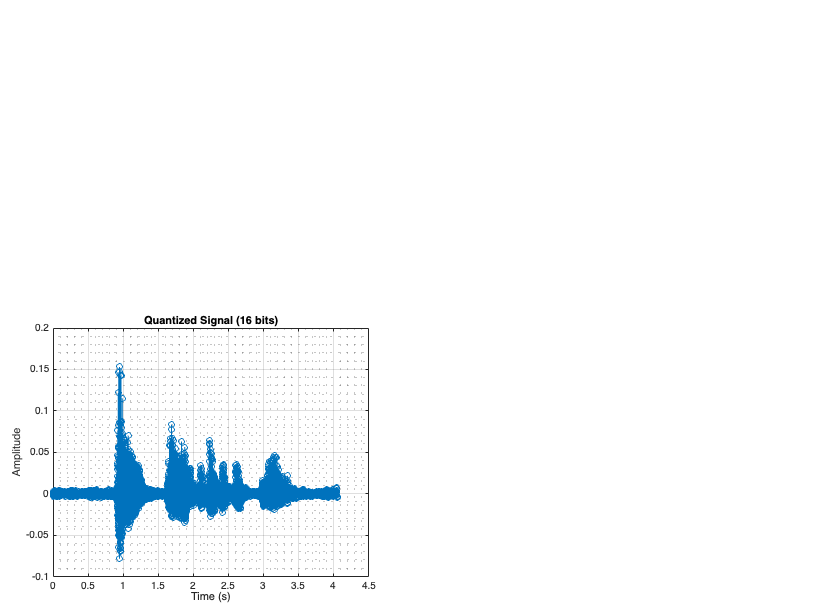

plot(t_downsampled, y_quantized, 'o-');
title(['Quantized Signal (' num2str(bits) ' bits)']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
grid minor;

## Reconstructed Signal with Linear Interpolation

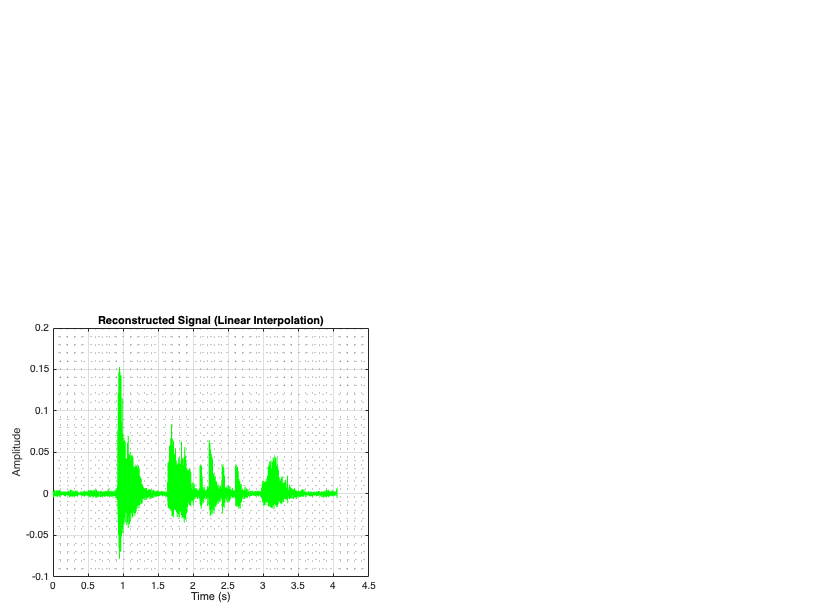

plot(t_reconstructed, y_reconstructed_linear, 'g');
title('Reconstructed Signal (Linear Interpolation)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
grid minor;

## Reconstructed Signal with Spline Interpolation

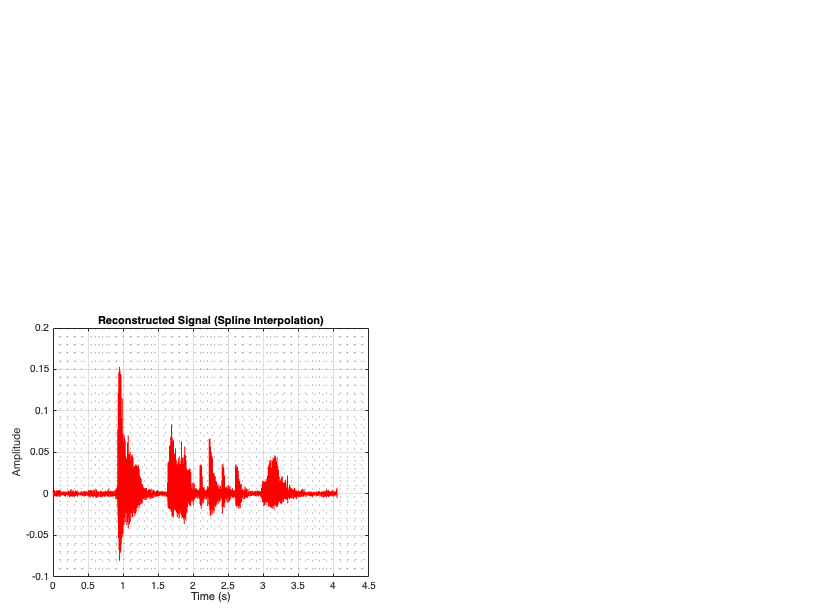

plot(t_reconstructed, y_reconstructed_spline, 'r');
title('Reconstructed Signal (Spline Interpolation)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
grid minor;

## Convert reconstructed signal back to audio file

% Write the reconstructed signal to a new WAV file
audiowrite('reconstructed_spline_audio.wav', y_reconstructed_spline, Fs);
audiowrite('reconstructed_linear_audio.wav', y_reconstructed_linear, Fs);

[audio, fs] = audioread('reconstructed_spline_audio.wav'); % Load your audio file here
audio_normalized = int16(audio * 32767); % Normalize
audio_binary = dec2bin(typecast(audio_normalized(:), 'uint16'), 16); % Convert to binary
binary_vector = audio_binary(:)'; % Reshape to vector for transmission

% Convert string of '0' and '1' characters to uint8 array
num_bytes = floor(length(binary_vector)/8);
binary_data = zeros(1, num_bytes, 'uint8');

% Process 8 bits at a time
for i = 1:num_bytes
    byte_str = binary_vector((i-1)*8 + 1 : i*8);
    binary_data(i) = bin2dec(byte_str);
end

% Write to binary file
fid = fopen('audio_binary.bin', 'wb');
fwrite(fid, binary_data, 'uint8');
fclose(fid);

% Verify file size
fileinfo = dir('audio_binary.bin');
fprintf('Binary file size: %.2f KB\n', fileinfo.bytes/1024);

Binary file size: 379.88 KB



% To read the file back:
fid = fopen('audio_binary.bin', 'rb');
read_data = fread(fid, inf, 'uint8');
fclose(fid);

% Optionally, you can play the reconstructed audio
% sound(y_reconstructed_spline, Fs);
% sound(y_reconstructed_linear, Fs)